## Program for analysing kinematics of multibody systems

Plan of action:

- Generate input data structure based on the example of slider crank

- Generate constraints and it derivatives (e.g., Newton-Raphson requires constraint vector and it's Jacobian).

- Solve system using NR and advance in time. Store data.

- After solution, make some ilustrative plots.

### Example: slider crank

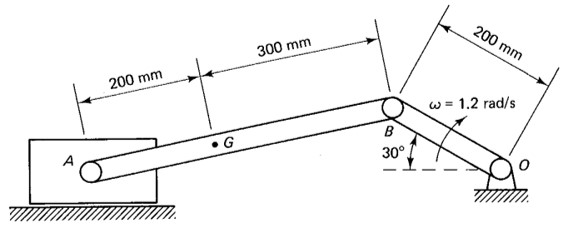

Body numbering

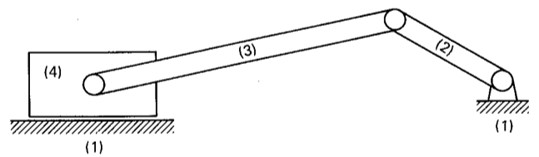

Local coordinate frames

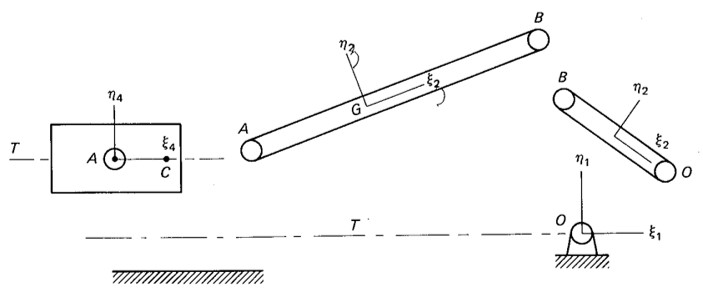

Data from the user

- Bodies and their coordinate frames.

- Joints and their characteristic points

- Solver settings

### Bodies and coordinates

mbs = init_mbs();
mbs = add_body(mbs, "ground");
mbs = add_body(mbs, "crank", -0.1, 0.1, -deg2rad(30));
mbs = add_body(mbs, "link", -0.45, 0.1, deg2rad(15));
mbs = add_body(mbs, "slider", -0.6)

mbs = struct with fields:
    bodies: [1×4 struct]
    joints: [1×1 struct]


### Joints and characteristic points

Vectors that points to joint locations are in local coordinate frame. They do not change locations in time.

mbs = add_revolute(mbs, "revO", "ground", [0; 0], "crank", [0.1, 0.0]);
mbs = add_revolute(mbs, "revB", "crank", [-0.1; 0], "link", [0.3, 0.0]);
mbs = add_revolute(mbs, "revA", "link", [-0.2; 0], "slider", [0.0, 0.0]);

% Simple joints
mbs = add_simple_joint(mbs, "groundx", "ground", "x", 0);
mbs = add_simple_joint(mbs, "groundy", "ground", "y", 0);
mbs = add_simple_joint(mbs, "groundangle", "ground", "fi", 0);

mbs = add_simple_joint(mbs, "slidertranslation", "slider", "y", 0);
mbs = add_simple_joint(mbs, "sliderrotation", "slider", "fi", 0);

% Driving constraint for the crank
om = 1.2; % rad/s
mbs = add_driving_joint(mbs, "crankrotation", "crank", "fi", @(t)-deg2rad(30) - om * t);

### Basic checking

fprintf("System has %d bodies and %d coordinates.\n", length(mbs.bodies), 3 * length(mbs.bodies))

System has 4 bodies and 12 coordinates.


fprintf("Number of the joints:\n\tRevolute: %d\n\tPrismatic: %d\n", ...
    length(mbs.joints.revolute), length(mbs.joints.prismatic))

Number of the joints:
	Revolute: 3
	Prismatic: 0


fprintf("\tSimple: %d\n\tDriving: %d\n", length(mbs.joints.simple), length(mbs.joints.driving))

	Simple: 5
	Driving: 1


fprintf("In total %d DOF are constrained!\n", ...
    sum([2, 2, 1, 1] .* [length(mbs.joints.revolute), length(mbs.joints.prismatic), ...
    length(mbs.joints.simple), length(mbs.joints.driving)]))

In total 12 DOF are constrained!
